# 本代码为学习笔记

## 测试1

% 对于solve函数是允许做如下运算的
syms x y
s = x + 1 + y; 
eq1 = y - s*x-1;
eq2 = y + 1 -6;

ss = solve(eq1,eq2);
ss.x

$$ans = \left(\begin{array}{c} -\sqrt{13}-3\\ \sqrt{13}-3 \end{array}\right)$$

ss.y

$$ans = \left(\begin{array}{c} 5\\ 5 \end{array}\right)$$

## 测试2

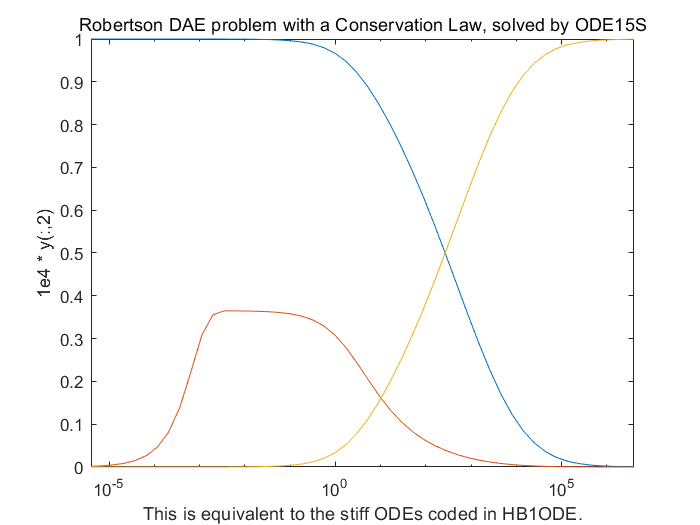

M = [1 0 0
   0 1 0
   0 0 0];


y0 = [1; 0; 1e-3];
tspan = [0 4*logspace(-6,6)];
options = odeset('Mass',M,'RelTol',1e-4,'AbsTol',[1e-6 1e-10 1e-6], ...
   'Vectorized','on');
c=3;
[t,y] = ode15s(@f,tspan,y0,options,c);

y(:,2) = 1e4*y(:,2);
figure;
semilogx(t,y);
ylabel('1e4 * y(:,2)');
title('Robertson DAE problem with a Conservation Law, solved by ODE15S');
xlabel('This is equivalent to the stiff ODEs coded in HB1ODE.');

## 测试3

x = fsolve(@myfunction,[1.5, 2.5])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     2.0000    3.0000


function out = f(t,y,c)
r1 = -0.04*y(1,:) + 1e4*y(2,:).*y(3,:);
r2 = 0.04*y(1,:) - 1e4*y(2,:).*y(3,:) - 3e7*y(2,:).^2;
r3 = y(1,:) + y(2,:) + y(3,:) - 4+c;
out = [ r1
    r2
    r3];
end
function [dx,y] = myfunction(x)
dx(1,1) = x(1)+x(2)-5;
dx(2,1) = x(2)^2-9;
y(1) = x(1);
y(2) = x(2);

end